# Exam F20

## Question 1

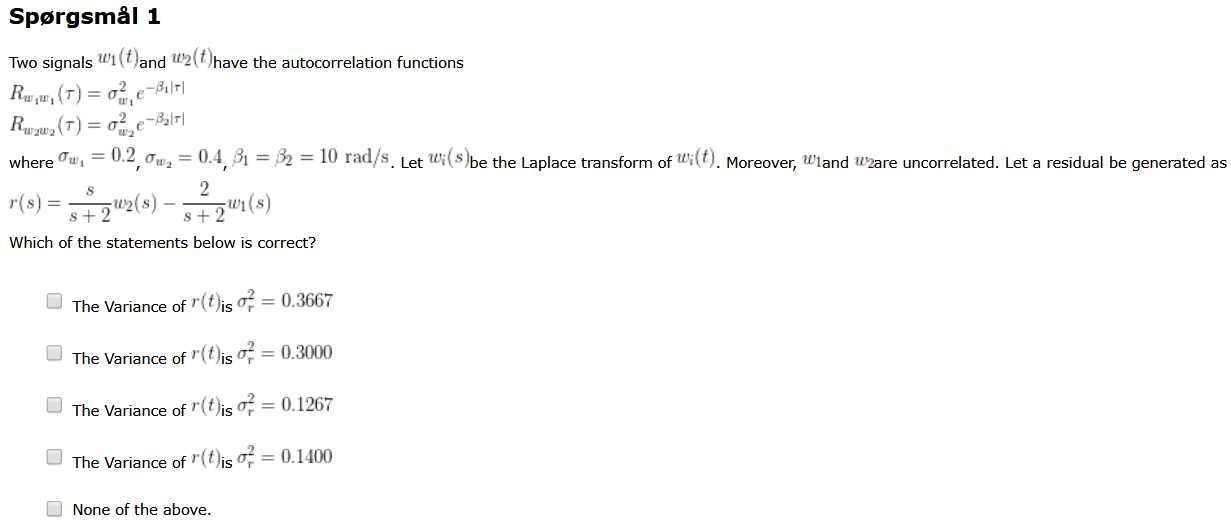

syms beta1 beta2
sigma1 = 0.2^2; sigma2 = 0.4^2;
r1 = subs((2/(beta1 + 2))*sigma1, beta1, 10);

$$r1 = \frac{1}{150}$$

r2 = subs((beta2/(beta2 + 2))*sigma2, beta2, 10);

$$r2 = \frac{2}{15}$$

vpa(r1 + r2)

$$ans = 0.14$$

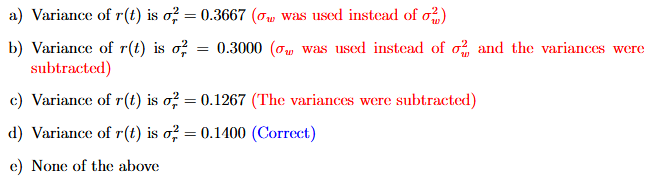

## Question 2

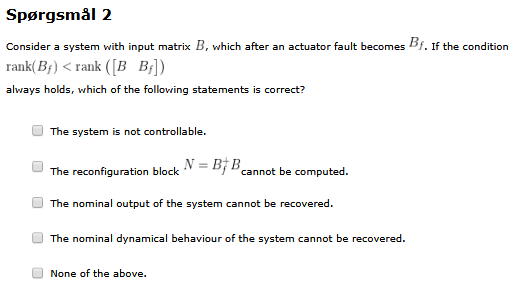

If same rank -> perfect matching

System can still be controllable. Reconfiguration block can always be computed.

Reconfiguration is a method to get same output (that's the purpose, to control a system even though there is faults), but the dynamical behavior changes.

## Question 3

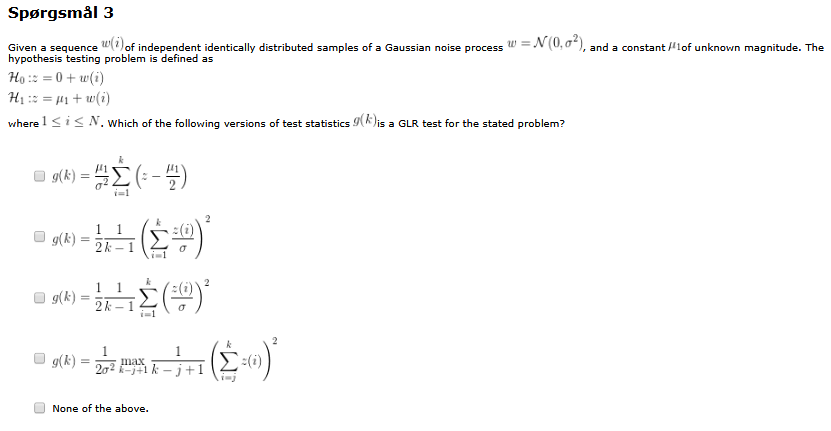

From slides:

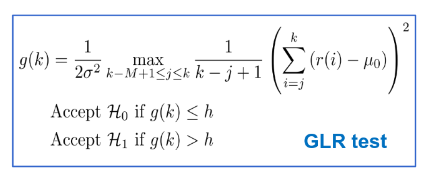

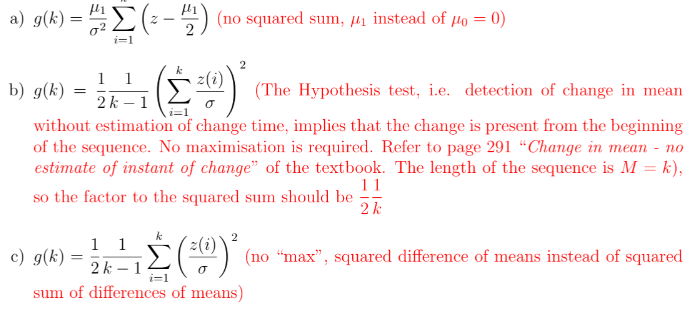

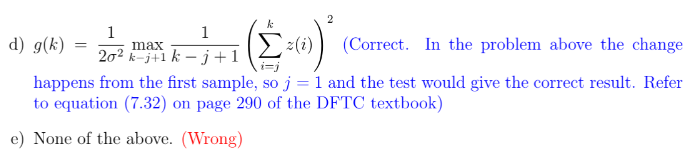

## Question 4

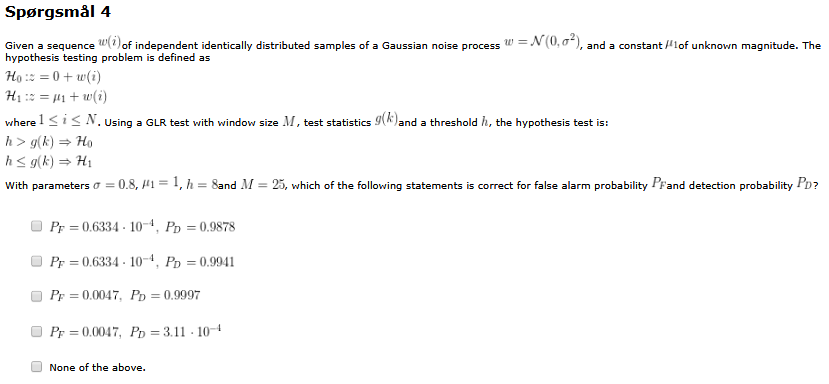

h = 8; M = 25; sigma = 0.8; mu1 = 1; mu0 = 0; 
P_F = 1 - chi2cdf(2*h, 1)

P_F = 6.3342e-05

lambda = (M*(mu1-mu0)^2)/(sigma^2);
P_D = 1 - ncx2cdf(2*h, 1, lambda)

P_D = 0.9878

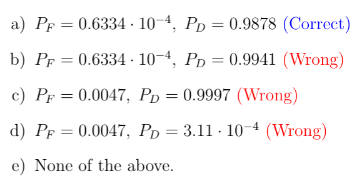

## Question 5

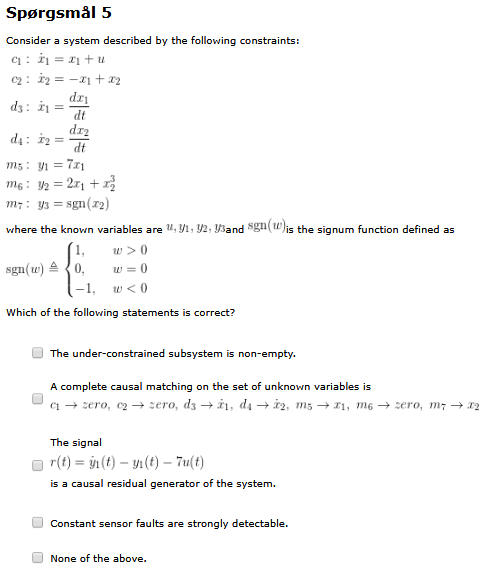

clc
clear all

% Inputs
syms u(t) % Symbolic input declaration
ST_input(1,:) = {u}; % symbolic variable
ST_input(2,:) = {'u\\left(t\\right)'}; % LaTeX expression


% Measurements
syms y1(t) y2(t) y3(t) % Symbolic measurement declaration
ST_meas(1,:) = {y1, y2, y3}; % symbolic variable
ST_meas(2,:) = {'y1\\left(t\\right)', 'y2\\left(t\\right)', 'y3\\left(t\\right)'}; % LaTeX expression

% Parameters
syms a % Symbolic parameters declaration
ST_parameters(1,:) = {a}; % symbolic variable
ST_parameters(2,:) = {'a'}; % LaTeX expression

% Unknowns
syms x1(t) x2(t) dx1(t) dx2(t) %Symbolic unknowns declaration
ST_unknowns(1,:) = {x1, x2, dx1, dx2}; % symbolic variable
ST_unknowns(2,:) = {'x1', 'x2', '\dot x_1', '\dot x_2'}; % LaTeX expression

% Enter the constraints of the system
% ST_cons(1.:) comprise the Matlab names of constraints
% ST_cons(2.:) comprise the Latex
% ST_cons(3,:) comprise a cell array list with the expressions of the constraints



ST_cons(1,:) = {'c1','c2','d3','d4','m5','m6', 'm7'}; % Constraint names
ST_cons(2,:) = {'c_1','c_2','d_3', 'd_4', 'm_5', 'm_6', 'm_7'}; % Constraint latex names
ST_cons(3,:) = {...
                0 == dx1 - x1 + u,...
                0 == dx2 + x1 - x2,...
                0 == dx1 - diff(x1, t),...
                0 == dx2 - diff(x2, t),...
                0 == y1 - 7*x1,...
                0 == y2 - 2*x1 - x2^3,...
                0 == y3 - sign(x2)};
% NOTE that "diff(.,t)" is used as the differential operator, D == d/dt.
ST_canfail  = [1:2, 5:7]; % constraint d7-d12 cannot fail
ST_domains  = [1 1 1 1 1 1 1];


% Automatic incMatrix generation
cons_oneway = {[],[],{x1},{x2},[],[], []};
ST_IncMat = sa_incidencematrix(ST_cons,...
    ST_input,ST_meas,...
    ST_unknowns,cons_oneway);

% disp(ST_IncMat)

ST_sys =...
    sa_create(ST_IncMat,ST_cons,...
    ST_input, ST_meas,ST_unknowns,...
    ST_domains, ST_canfail,...
    ST_parameters);

sa_disp(ST_sys);

System with 7 constraint(s), 1 input(s), 3 measurement(s) and
            4 unknown variable(s).


ST_sys = sa_match(ST_sys,'mso'); % alternatively 'rank' MSO

disp('Obtained matching:');

Obtained matching:


sa_disp(ST_sys, 't')

  |     c1 |     c2 |     d3 |     d4 |     m5 |     m6 |     m7
----------------------------------------------------------------
1 |      - |      - |      - |      - |      0 |  x1(t) |  x2(t)
2 |      - | dx2(t) |      - |      0 |      - |  x1(t) |  x2(t)
3 |      - | dx2(t) |      - |      0 |  x1(t) |      - |  x2(t)
4 |      - | dx2(t) |      - |      0 |  x1(t) |  x2(t) |      -
5 | dx1(t) |      - |      0 |      - |      - |  x1(t) |  x2(t)
6 | dx1(t) |      - |      0 |      - |  x1(t) |      - |      -
7 | dx1(t) |  x1(t) |      0 | dx2(t) |      - |      - |  x2(t)
8 | dx1(t) |  x2(t) |      0 | dx2(t) |      - |  x1(t) |      -



disp('Parity relation symbolic form:')

Parity relation symbolic form:


sa_disp(ST_sys, 's')

Matching 1:
  m5(y1,m6(y2,m7(y3)))

Matching 2:
  d4(m7(y3),c2(m6(y2,m7(y3)),m7(y3)))

Matching 3:
  d4(m7(y3),c2(m5(y1),m7(y3)))

Matching 4:
  d4(m6(y2,m5(y1)),c2(m5(y1),m6(y2,m5(y1))))

Matching 5:
  d3(m6(y2,m7(y3)),c1(u,m6(y2,m7(y3))))

Matching 6:
  d3(m5(y1),c1(u,m5(y1)))

Matching 7:
  d3(c2(m7(y3),d4(m7(y3))),c1(u,c2(m7(y3),d4(m7(y3)))))

Matching 8:
  d3(m6(y2,c2(m6(...),d4(c2(...)))),c1(u,m6(y2,c2(m6(...),d4(c2(...))))))



disp('Parity relation analytic form:')

Parity relation analytic form:


sa_disp(ST_sys, 'a')

Matching 1:
  0 == y1(t) - (7*y2(t))/2 + (7*y3(t)^3)/2

Matching 2:
  0 == y3(t) - y2(t)/2 + y3(t)^3/2 - diff(y3(t), t)

Matching 3:
  0 == y3(t) - y1(t)/7 - diff(y3(t), t)

Matching 4:
  0 == ((2*diff(y1(t), t))/7 - diff(y2(t), t))/(3*(y2(t) - (2*y1(t))/7)^(2/3)) - y1(t)/7 + (y2(t) - 2*x1(t))^(1/3)

Matching 5:
  0 == y2(t)/2 - u(t) - x2(t)^3/2 + (3*y3(t)^2*diff(y3(t), t))/2 - diff(y2(t), t)/2

Matching 6:
  0 == y1(t)/7 - u(t) - diff(y1(t), t)/7

Matching 7:
  0 == x2(t) - u(t) - dx2(t) - diff(y3(t), t) + diff(y3(t), t, t)

Matching 8:
  0 == y2(t)/2 - u(t) - x2(t)^3/2 - diff(y2(t), t)/2 + (3*(diff(y2(t), t)/2 - (3*x2(t)^2*diff(x2(t), t))/2 + diff(dx2(t), t, t) + diff(x1(t), t, t))*(y2(t)/2 - x2(t)^3/2 + diff(dx2(t), t) + diff(x1(t), t))^2)/2



Option c is false.

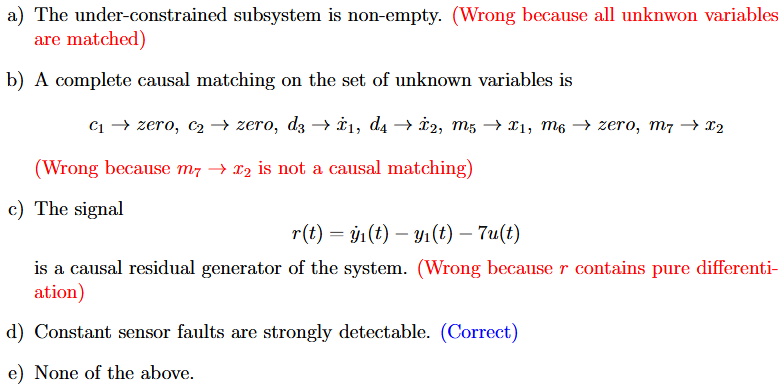

## Question 6

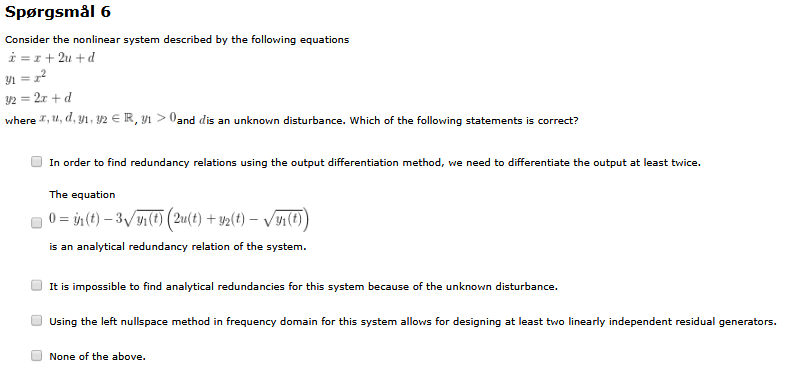

% Inputs
clear all;

System with 5 constraint(s), 1 input(s), 2 measurement(s) and
            4 unknown variable(s).


Obtained matching:


  |     c1 |     c2 |     c3 |     d4 |     c5
----------------------------------------------
1 |      0 |  x1(t) |   d(t) | dx1(t) |      -



Parity relation symbolic form:


Matching 1:
  c1(u1,c2(y1),d4(c2(y1)),c3(y2,c2(y1)))



Parity relation analytic form:


Matching 1:
  0 == 2*u1(t) + y2(t) - y1(t)^(1/2) - diff(y1(t), t)/(2*y1(t)^(1/2))



close all;
clc;
syms u1(t) % Symbolic input declaration
ST_input(1,:) = {u1}; % symbolic variable
% Measurements
syms y1(t) y2(t) % Symbolic measurement declaration
ST_meas(1,:) = {y1, y2}; % symbolic variable
% Unknowns
syms x1(t) dx1(t) dy1(t) d(t)  %Symbolic unknowns declaration
ST_unknowns(1,:) = {x1,dx1,dy1,d}; % symbolic variable

ST_cons(1,:) = {'c1','c2','c3','d4','c5'}; % Constraint names
ST_cons(3,:) = {...
                0 == -dx1 + x1 + 2*u1 + d,...
                0 == x1^2 - y1,...
                0 == - y2 + 2*x1+d,...
                0 == diff(x1,t) - dx1 ,...
                0 == dy1 - dx1^2};

% NOTE that "diff(.,t)" is used as the differential operator, D == d/dt.
ST_canfail  = [4]; % constraint d7-d12 cannot fail
ST_domains  = [1 1 1 1 1];


% Automatic incMatrix generation
cons_oneway = {[],[],{x1},[], []};
ST_IncMat = sa_incidencematrix(ST_cons,...
    ST_input,ST_meas,...
    ST_unknowns,cons_oneway);

% disp(ST_IncMat)

ST_sys =...
    sa_create(ST_IncMat,ST_cons,...
    ST_input, ST_meas,ST_unknowns,...
    ST_domains, ST_canfail);

sa_disp(ST_sys);
ST_sys=sa_match(ST_sys,'rank'); % alternatively 'rank' MSO

disp('Obtained matching:');
sa_disp(ST_sys, 't')
disp('Parity relation symbolic form:')
sa_disp(ST_sys, 's')
disp('Parity relation analytic form:')
sa_disp(ST_sys, 'a')
pretty(2*u1(t) + y2(t) - y1(t)^(1/2) - diff(y1(t), t)/(2*y1(t)^(1/2)))

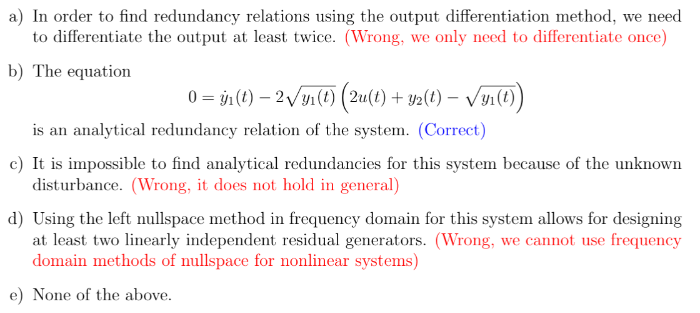

## Question 7

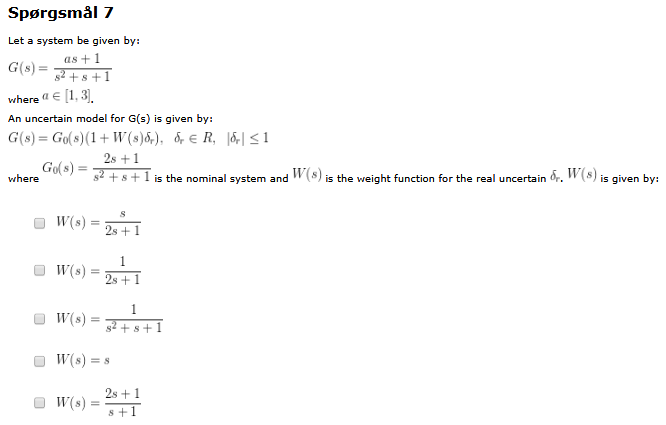

syms s a

                                    d
                                   -- y1(t)
                                   dt
2 u1(t) + y2(t) - sqrt(y1(t)) - -------------
                                2 sqrt(y1(t))



G = (a*s + 1)/(s^2 + s +1);
G0 = (2*s + 1)/(s^2 + s + 1);
simplify(subs(G/G0 - 1, a, 1))
simplify(subs(G/G0 - 1, a, 3))

Option a fits the bill

## Question 8

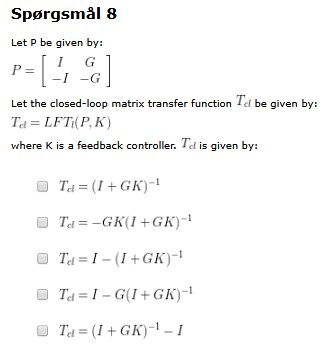

clear all; clc;
syms G K I;

% Define the correct P matrix

$$ans = -\frac{s}{2\,s+1}$$

P = [I G

$$ans = \frac{s}{2\,s+1}$$

    -I -G]
% Define the submatrices
P11 = P(1, 1); P21 = P(1, 2);
P12 = P(2, 1); P22 = P(2, 2);

% Compute the lower LFT: T_cl = P11 + P12*K*(I - P22*K)^(-1)*P21
T_cl = simplify(P11 + P12*K*inv(1-P22*K)*P21);

% Closed-loop transfer function Tcl = [S T]

$$P = \left(\begin{array}{cc} \text{I} & G\\ -\text{I} & -G \end{array}\right)$$

disp(T_cl)


$$T_{\textrm{cl}} =\frac{I}{\textrm{GK}+1}={\left(I+\textrm{GK}\right)}^{-1}$$


Option a is correct.

## Question 9

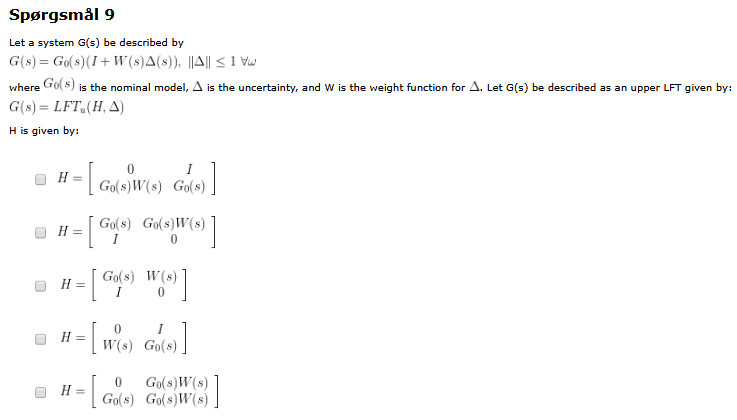

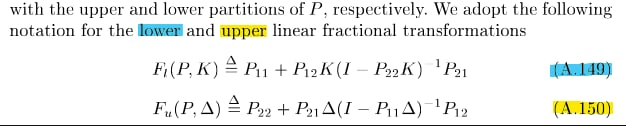

We are looking for the upper. Insert $G_0$ into the paranthesis and match with $F_u \left(P,\Delta \right)$.


$$G\left(s\right)=G_0 +G_0 W\Delta$$


syms G0 W I
P = [0 I
     G0*W G0]

$$\frac{\text{I}}{G\,K+1}$$

$$P = \left(\begin{array}{cc} 0 & \text{I}\\ G_{0}\,W & G_{0} \end{array}\right)$$

## Question 10

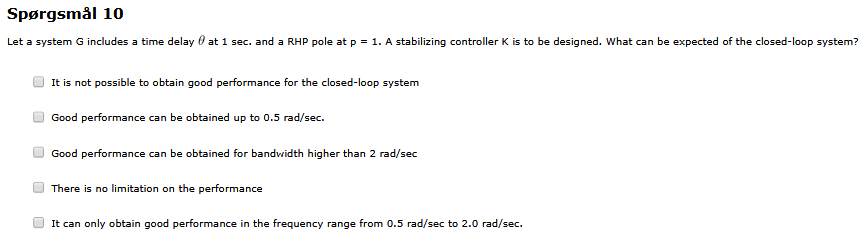

## Question 11

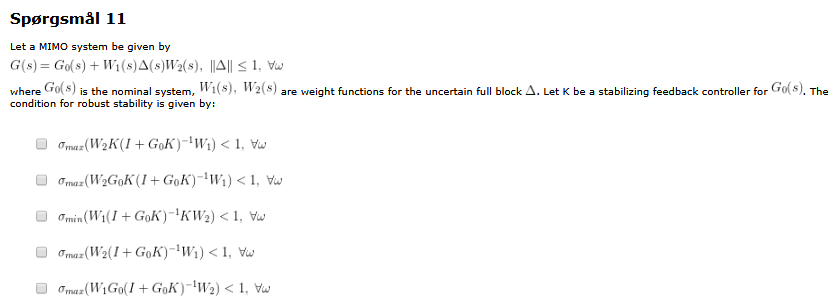

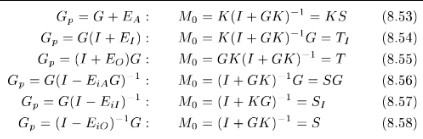a and d are additive. Rest is multiplicative.


$$E=W_2 \Delta W_1$$



$$G=G_0 +E$$


The question give it in the wrong way, so we switch around: $G=G_0 +W_1 \Delta W_2$.

The system given is equivalent to Eq. 8.53: $M_0 =K{\left(I+\textrm{GK}\right)}^{-1}$

$M=W_1 M_0 W_2$, but since we switched the weight functions we have: $M=W_2 M_0 W_1$

Inserting $M_0$: $M=W_2 K{\left(I+\textrm{GK}\right)}^{-1} W_1$

Option a is correct.

## Question 12 - broken

$W_T$ can't be found.